## Preprocess and Explore Data

## Represent data in MATLAB

Load the data from the previous step

load rawData.mat
% data

## Select data of interest

SelectRearrangeData;

## Preprocess data by type

### Clean up times and determine storm duration

PreprocessByTime;

tmin = datetime
   01-Jan-2017 00:00:00

tmax = datetime
   30-Nov-2020 23:00:00

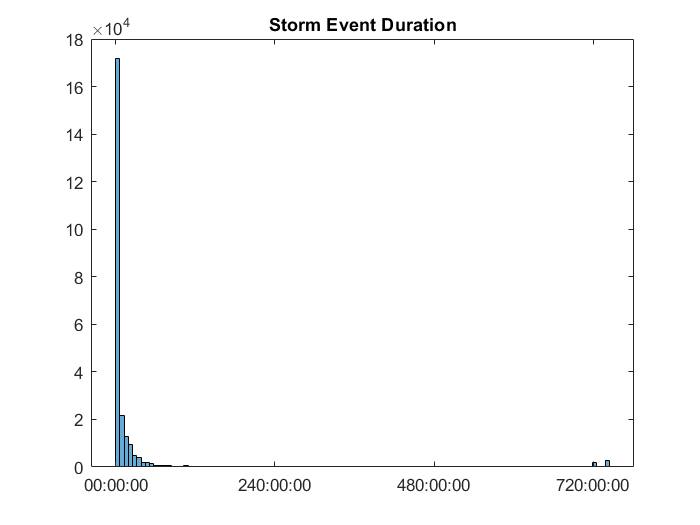

histogram(data.storm_duration)
title("Storm Event Duration")

The longest storm(s) lasted for a month! Examine these storms.

[maxDur,idx] = maxk(data.storm_duration,10);
longestStormDur = data(idx,:)

longestStormDur = 10×10 timetable
            Time                state        event_type    damage_property    damage_crops    begin_lat    begin_lon    end_lat    end_lon                                                                                                                                         event_narrative                                                                                                                                          storm_duration
    ____________________    _____________    __________    _______________    ____________    _________    _________    _______    _______    _________________________________

### Combine similar storm categories

head(data(:,vartype("categorical")))

ans = 8×2 timetable
            Time             state      event_type
    ____________________    ________    __________
    01-Jan-2017 00:00:00    TEXAS        Drought  
    01-Jan-2017 00:00:00    TEXAS        Drought  
    01-Jan-2017 00:00:00    TEXAS        Drought  
    01-Jan-2017 00:00:00    TEXAS        Drought  
    01-Jan-2017 00:00:00    ARKANSAS     Drought  
    01-Jan-2017 00:00:00    ARKANSAS     Drought  
    01-Jan-2017 00:00:00    ARKANSAS     Drought  
    01-Jan-2017 00:00:00    ALABAMA      Drought  

Visualize the event frequency (use the helper function `bigFigure` to see many categories)

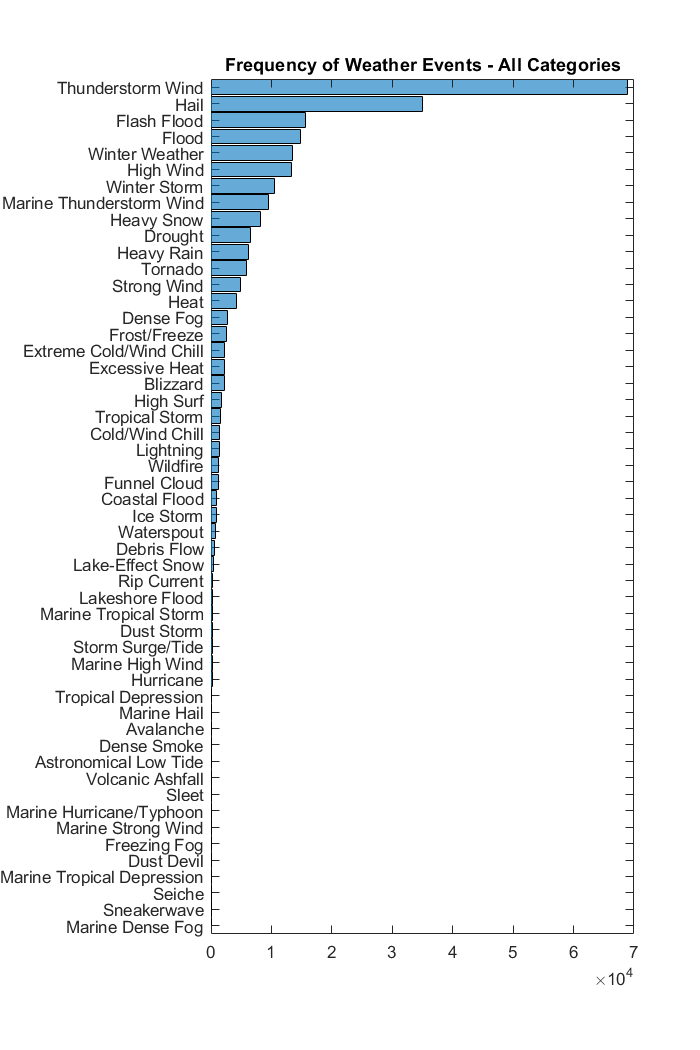

bigFigure("tall");
histogram(data.event_type,"Orientation","horizontal",...
    "DisplayOrder","ascend")
title("Frequency of Weather Events - All Categories")

Combine similar categories. 

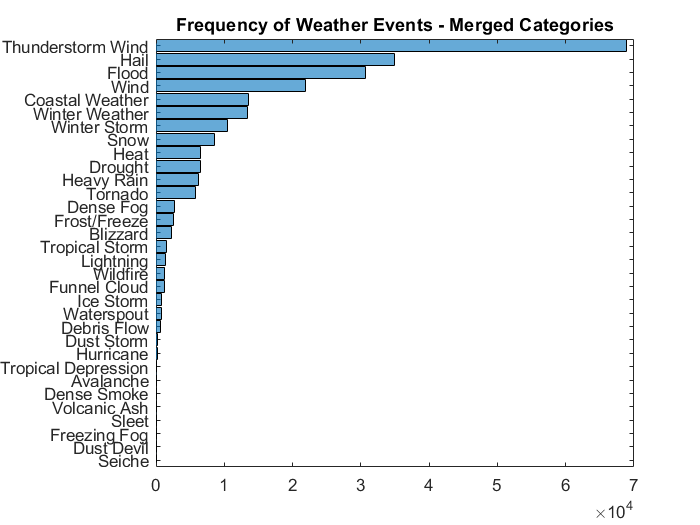

data = PreprocessCategories(data);   
figure
histogram(data.weathercats,"Orientation","horizontal",...
    "DisplayOrder","ascend")
title("Frequency of Weather Events - Merged Categories")

### Convert text data to numeric

Examine some random rows in the table to explore textual data.

datasample(data(:,vartype("string")),10)

ans = 10×7 timetable
            Time            damage_property    damage_crops    begin_lat    begin_lon      end_lat      end_lon                                                                                                                                                                                                                                          event_narrative                                                                                                                                                                                                                                    
    ____________________    _______________    ____________    _________    __________    _________    __________    __________

Convert locations and the damage costs containing "K" and "M" with the correct units using the helper function, `PreprocessStrings.mlx`. 

data = PreprocessStrings(data);
head(data)

ans = 8×12 timetable
            Time             state      event_type    damage_property    damage_crops    begin_lat    begin_lon    end_lat    end_lon                                                                                                                                         event_narrative                                                                                                                                          storm_duration    weathercats    damage_total
    ____________________    ________    __________    _______________    ____________    _________    _________    _______    _______   

## Explore data

Plot some of the events on a map and use the size of the bubble as the damage cost.

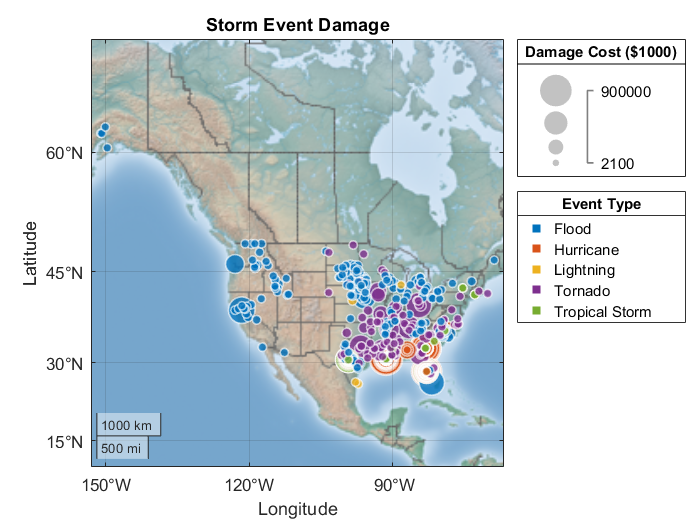

threshold = 2050;
plotEventCostsMap(data,threshold);

### Event frequency by location

Calculate damage costs by group.

damageByEvent = groupsummary(data,"weathercats",["mean","std"],"damage_total")

damageByEvent = 32×4 table
      weathercats      GroupCount    mean_damage_total    std_damage_total
    _______________    __________    _________________    ________________
    Avalanche              106              2.5798             20.824     
    Blizzard              2282              8.5473             102.43     
    Coastal Weather      13560              171.87             7842.6     
    Debris Flow            596              1153.8              25285     
    Dense Fog             2779             0.76563             7.9844     
    Dense Smoke             77                   0                  0     
    Drought               6532              27.254             368.26     
    Dust Devil              27               26.92              99.23     
    Dust Storm             273              7.8354              43.43     
    Flood   

topdamage = topkrows(damageByEvent,10,"mean_damage_total")

topdamage = 10×4 table
      weathercats      GroupCount    mean_damage_total    std_damage_total
    _______________    __________    _________________    ________________
    Hurricane              179          1.1254e+05           1.9491e+05   
    Tropical Storm        1491              4727.9                34169   
    Debris Flow            596              1153.8                25285   
    Wildfire              1315              863.36               7451.1   
    Tornado               5840              842.47                13678   
    Flood                30679              839.48                20646   
    Frost/Freeze          2619              183.41               2174.8   
    Wind                 21881              175.78               7566.8   
    Coastal Weather      13560              171.87               7842.6   
    Ice Storm   

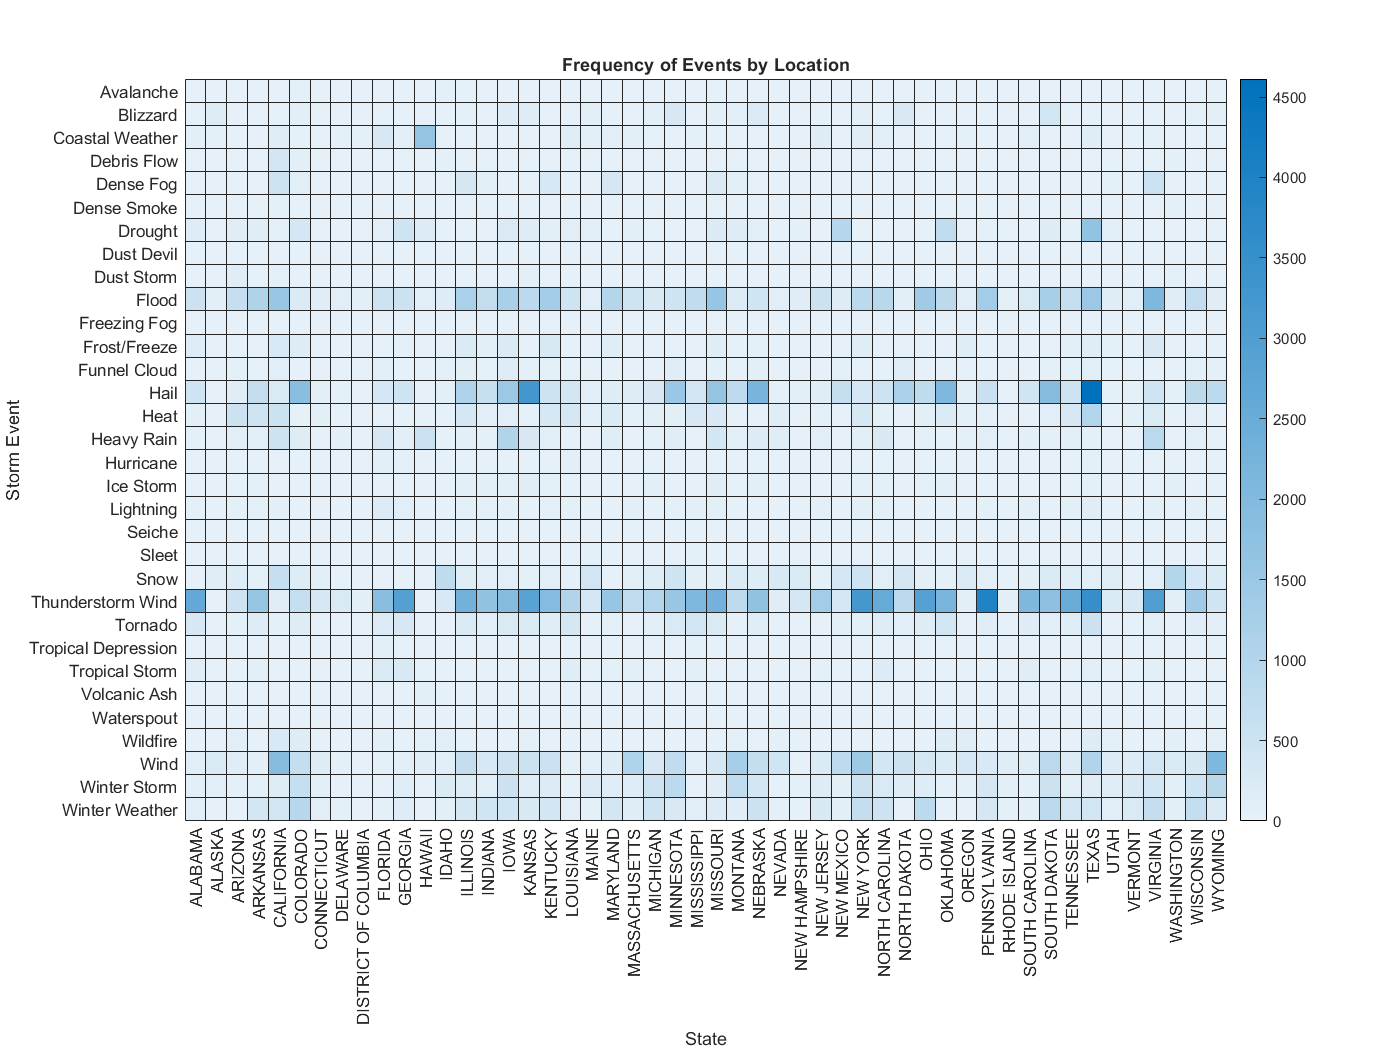

bigFigure;
heatmap(data,"state","weathercats"); 
xlabel("State")
ylabel("Storm Event")
title("Frequency of Events by Location")

### Compare damage cost by event and location

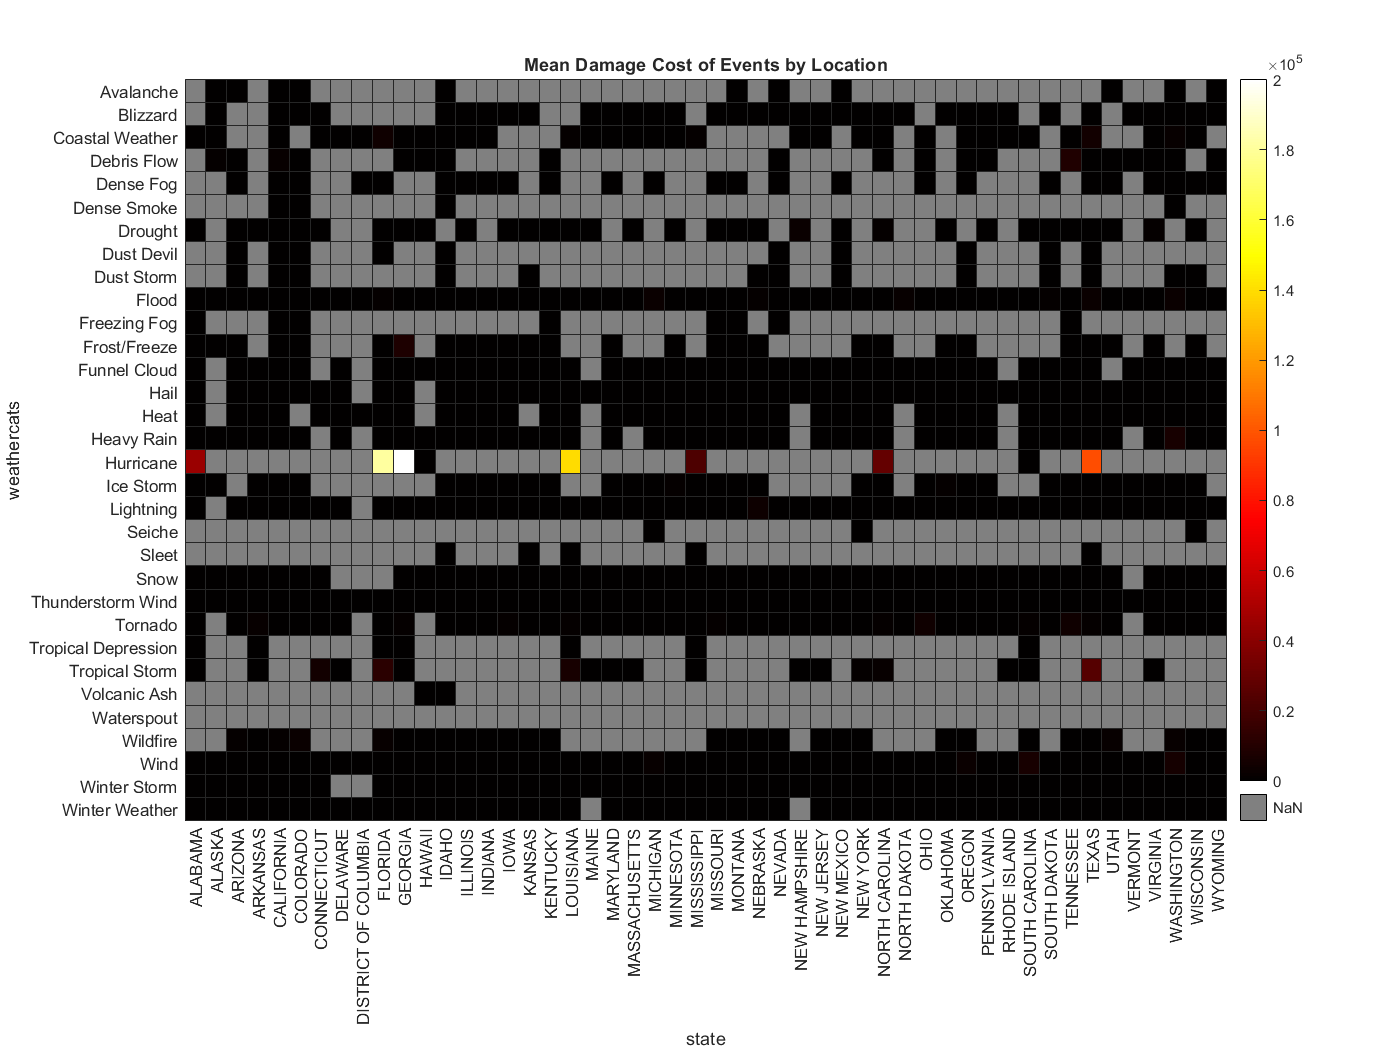

h = heatmap(data,"state","weathercats",...
    "ColorVariable","damage_total"); 
h.Colormap = hot;
h.MissingDataColor = [0.5 0.5 0.5];
title("Mean Damage Cost of Events by Location")

Explore damage costs with several visualizations.

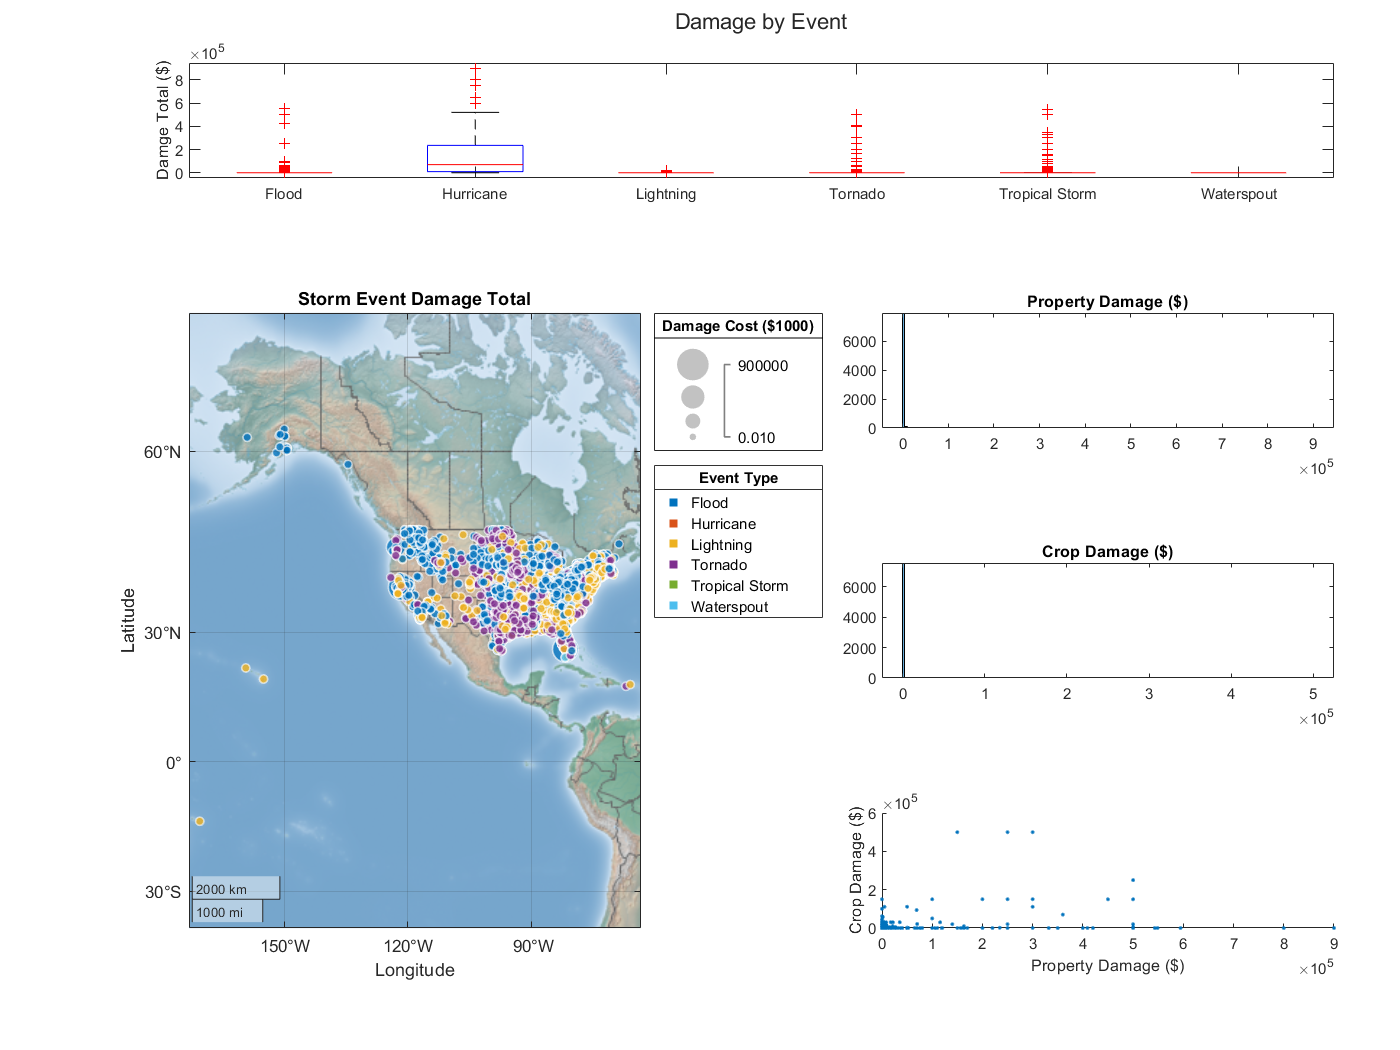

plotEventCosts(data)

### Explore event descriptions

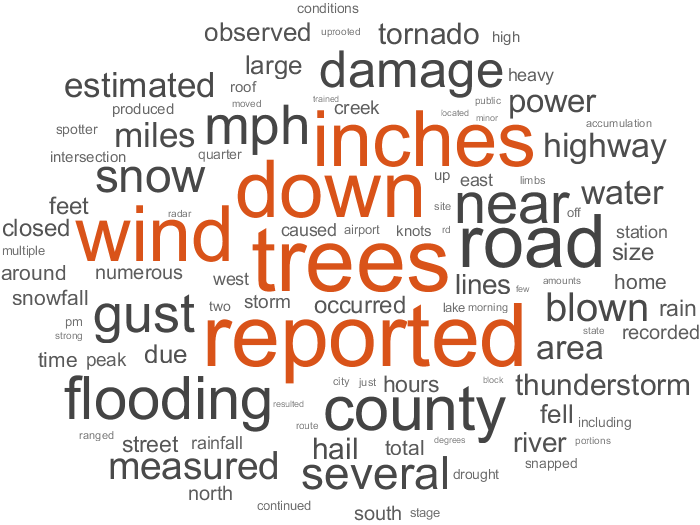

figure
wordcloud(data.event_narrative);

This indicates the most frequent events (wind, snow, flooding) and other related terms. Explore the text based on event type.

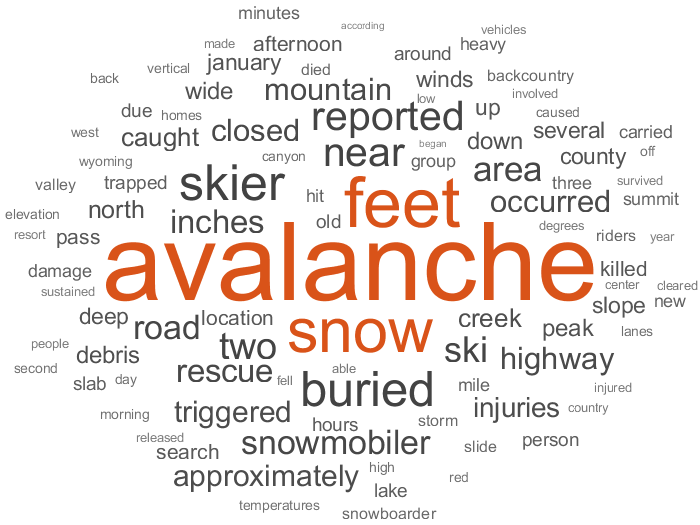

type = "Avalanche";

wordcloud(lower(data.event_narrative(data.event_type == type)));

## Work with missing data

There are missing data in a number of variables which may need different strategies. Various functions can help depending on your goals:

- `standardizeMissing`

- `ismissing`

- `rmmissing`

- `fillmissing`

Count the missing values in the table for each variable.

idx = ismissing(data);
sum(idx)

ans =        15189           0       47874       46812       83659       83659       83659       83659           0           0           0       41857


Remove rows with all missing data. 

data = rmmissing(data,"MinNumMissing",width(data));

Visualize the data set as a whole to allow us to see any remaining patterns of missing values using the function defined below.

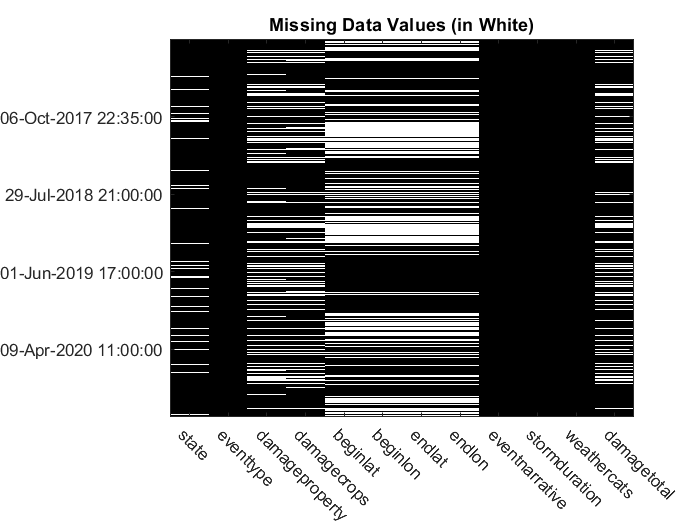

visualizeTableMask(data,idx);
title("Missing Data Values (in White)")

Some variables seem to have a significant number of missing values. Let's leave them in the data set for now and ignore them as needed.

Replace missing latitudes and longitudes with those of the US state.

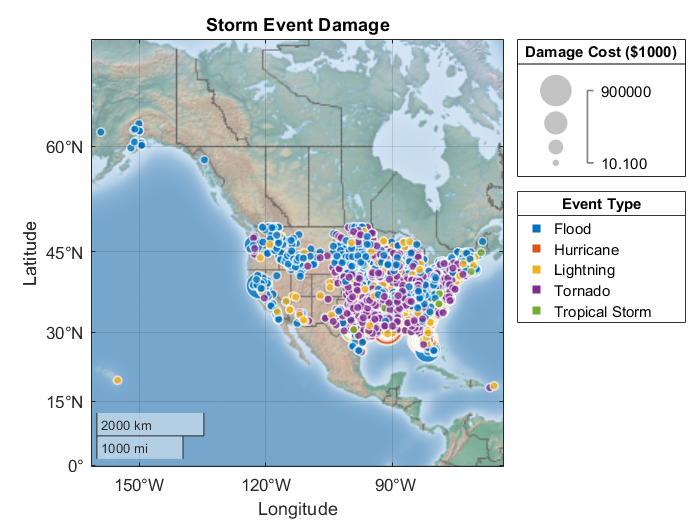

data = FillMissingLatLon(data);
plotEventCostsMap(data,10)

We may revisit additional strategies for the remaining missing data after exploring the data more thoroughly.

## Work with outliers

There are many outliers in this data set. Examine the ones in the damage costs.

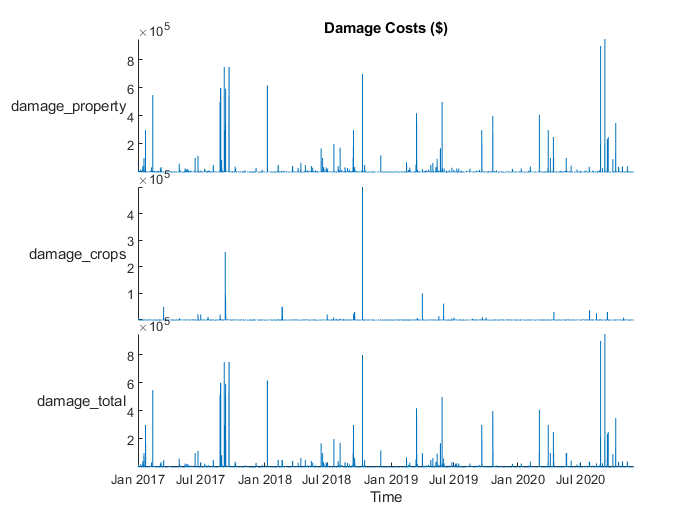

damage = data(:,startsWith(data.Properties.VariableNames,"damage_"));
stackedplot(damage);
title("Damage Costs ($)")

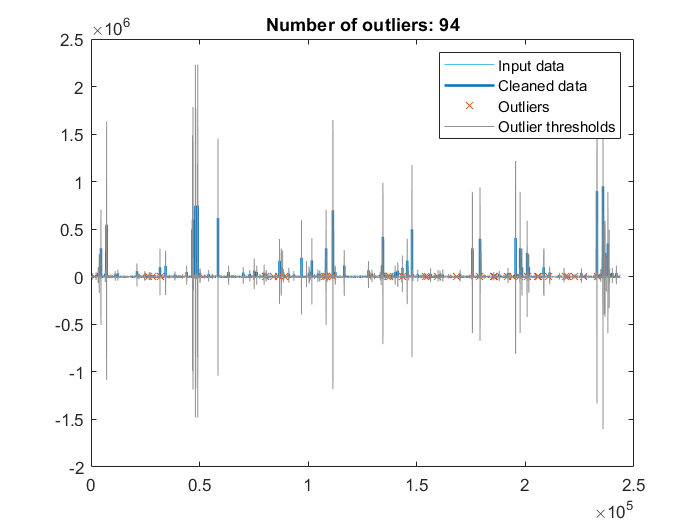

% Remove outliers
[cleanedData,outlierIndices] = rmoutliers(damage.damage_property,"movmean",3,...
    "ThresholdFactor",3.5);

% Display results
clf
plot(damage.damage_property,"Color",[77 190 238]/255,...
    "DisplayName","Input data")
hold on
plot(find(~outlierIndices),cleanedData,"Color",[0 114 189]/255,"LineWidth",1.5,...
    "DisplayName","Cleaned data")

% Plot outliers
plot(find(outlierIndices),damage.damage_property(outlierIndices),"x",...
    "Color",[217 83 25]/255,"DisplayName","Outliers")
title("Number of outliers: " + nnz(outlierIndices))

% Additional outlier computations for plot
[~,thresholdLow,thresholdHigh] = isoutlier(damage.damage_property,"movmean",3,...
    "ThresholdFactor",3.5);

% Plot outlier thresholds
plot([(1:numel(damage.damage_property))'; missing; (1:numel(damage.damage_property))'],...
    [thresholdHigh(:); missing; thresholdLow(:)],"Color",[145 145 145]/255,...
    "DisplayName","Outlier thresholds")

hold off
legend

clear thresholdLow thresholdHigh

Do this for all damage costs and visualize.

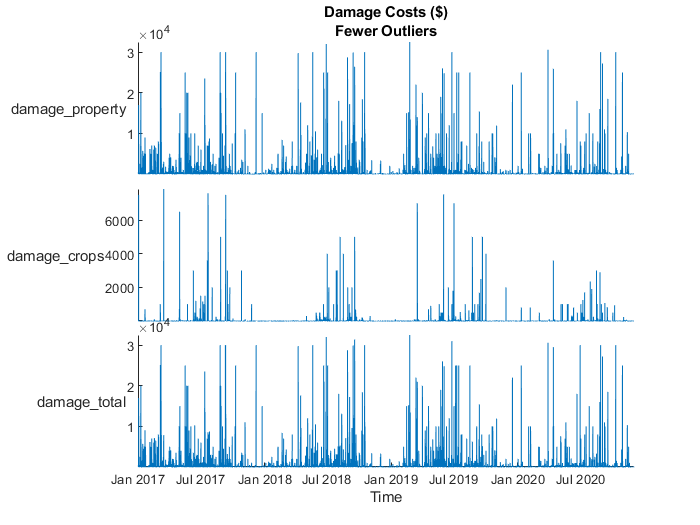

damage = rmoutliers(damage,"mean");
stackedplot(damage);
title(["Damage Costs ($)","Fewer Outliers"])

Save the prepped data

save PreprocessedData\preprocessedData2017_2020.mat

## Compare events to weather data

The script `compareLocalWeather` reads data from weather sensors at MathWorks headquarters in Natick, MA and synchronizes the weather data with the storm event data. Select the preprocessing steps to perform.

weather = 5577×8 timetable
         Timestamps         WindDir    WindSpeed    Humidity    TempF    Rain    Pressure    Power    Intensity
    ____________________    _______    _________    ________    _____    ____    ________    _____    _________
    11-Mar-2017 00:00:29       39         4.1          53       27.7      0        29.6        4         38    
    11-Mar-2017 00:01:30       38         4.3          53       27.7      0        29.6        4         46    
    11-Mar-2017 00:02:30       21         6.3          53       27.7      0        29.6        4         44    
    11-Mar-2017 00:03:31      357      

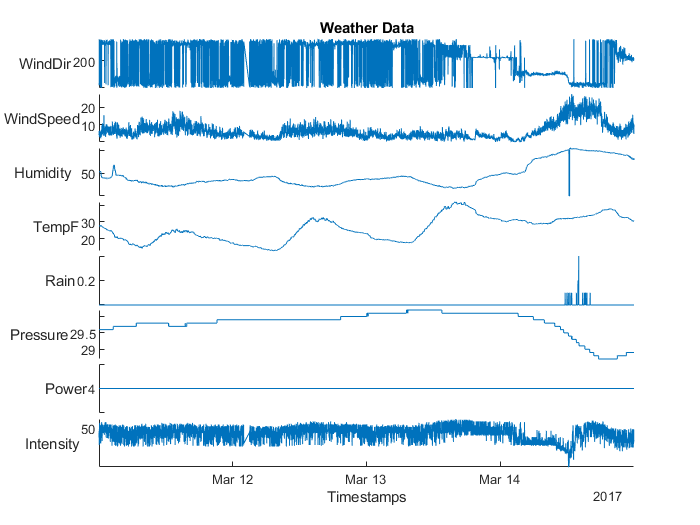

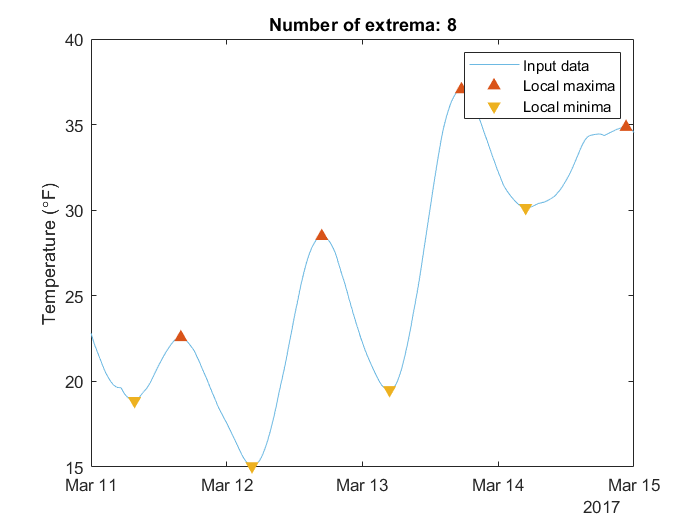

hiTemps = 4×8 timetable
         Timestamps         WindDir    WindSpeed    Humidity    TempF     Rain    Pressure    Power    Intensity
    ____________________    _______    _________    ________    ______    ____    ________    _____    _________
    11-Mar-2017 15:53:00    338.03       4.0968        27       23.913     0        29.8        4       44.871  
    12-Mar-2017 16:48:00      20.4          3.3        23        31.74     0        29.9        4         50.4  
    13-Mar-2017 17:30:00    259.11      0.28226        18       41.435     0        30.1        4           46  
    14-Mar-2017 22:36:00    232.02   

lowTemps = 4×8 timetable
         Timestamps         WindDir    WindSpeed    Humidity    TempF     Rain    Pressure    Power    Intensity
    ____________________    _______    _________    ________    ______    ____    ________    _____    _________
    11-Mar-2017 07:42:00    53.475      7.8098       29.426     15.043     0        29.8        4       50.738  
    12-Mar-2017 04:28:00    153.92      6.1738           39     14.685     0        29.9        4       40.443  
    13-Mar-2017 04:47:00       296      2.2306           41       18.6     0        30.1        4       46.177  
    14-Mar-2017 04:51:00    94.306  

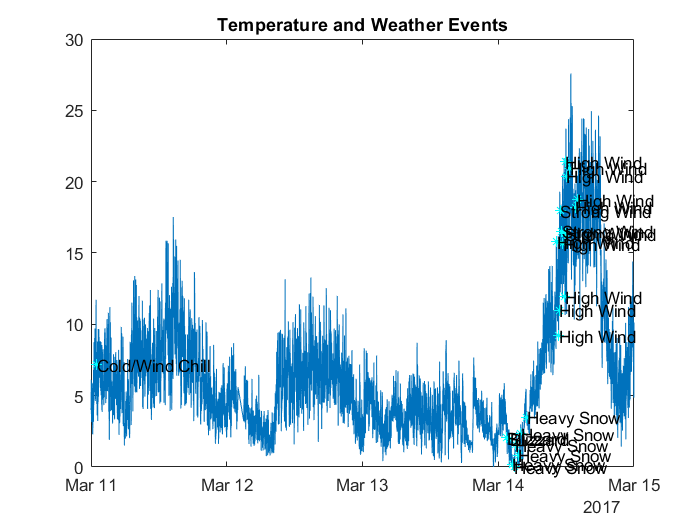

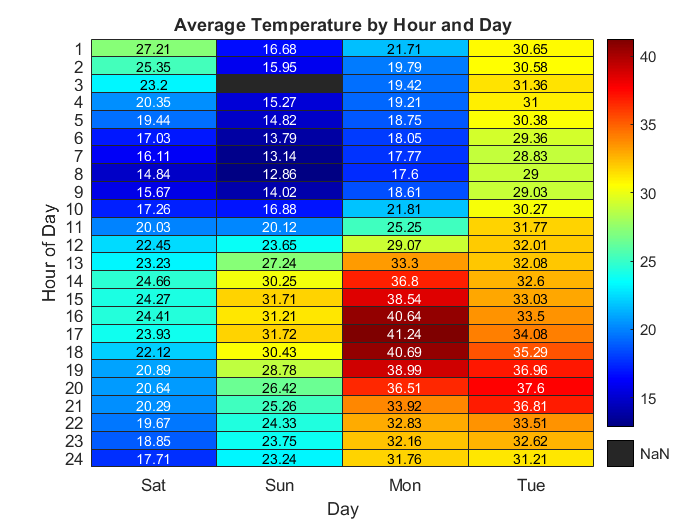

DetectFillOutliers = true;
DetectChangePoints = true;
NormalizeAndRescale = false;

CompareLocalWeather;

## Scale analysis

Repeat this analysis for data from all years since 1980 and get a sample of all data to build a model. See `PreprocessAllData.mlx` for details.

## Predict damage costs

Follow the script `PredictDamageCosts.mlx` to build a machine learning model (using the Regression Learner app) to predict the costs of events.

edit PredictDamageCosts

## Create Web App

Now this model can be used in an app to predict cost based on these variables. See `CreateWebApplication.mlx`

% EventDamageCosts

**Helper functions**

function visualizeTableMask(data,idx)
figure
imagesc(idx)
xticklabels(erase(data.Properties.VariableNames,"_"))
xticks(1:width(data))
xtickangle(-45)
ys = yticks;
yticklabels(cellstr(data.Time(ys)))
colormap gray
end

function plotEventCostsMap(data,threshold)
ev = ["Flood","Lightning","Tropical Storm","Hurricane",...
    "Waterspout","Tornado"];
idx = ismember(string(data.event_type),ev) & ...
    data.damage_total > threshold;
x = data(idx ,:);
x.weathercats = removecats(x.weathercats);
x = FillMissingLatLon(x);
figure
gb = geobubble(x,"begin_lat","begin_lon",...
    "SizeVariable","damage_total","ColorVariable","weathercats");
gb.Title = "Storm Event Damage";
gb.SizeLegendTitle = "Damage Cost ($1000)";
gb.ColorLegendTitle = "Event Type";
gb.Basemap = "colorterrain";
end

function data = FillMissingLatLon(data)
stateLatLon = struct2table(shaperead("usastatehi"));
idx = find(ismissing(data.begin_lat) & ismissing(data.begin_lon) & ~ismissing(data.state) & ...
    ismember(string(data.weathercats),["Tropical Storm","Hurricane",...
    "Waterspout"]));
for ii = 1:length(idx)
    sidx = lower(stateLatLon.Name) == lower(string(data.state(idx(ii))));
    data.begin_lat(idx(ii)) = stateLatLon.LabelLat(sidx);
    data.begin_lon(idx(ii)) = stateLatLon.LabelLon(sidx);
end
end

function plotEventCosts(data)
ev = ["Flood","Lightning","Tropical Storm","Hurricane",...
    "Waterspout","Tornado"];
idx = ismember(string(data.event_type),ev) & ...
    data.damage_total > 0;
x = data(idx ,:);
x.weathercats = removecats(x.weathercats);
warning("off","MATLAB:handle_graphics:Layout:NoPositionSetInTiledChartLayout")
% Create figure
t = tiledlayout(4,2,"TileSpacing","compact","Padding","compact");  %#ok
nexttile([1 2])
boxplot(x.damage_total,x.event_type)
ylabel("Damge Total ($)")
nexttile(3,[3 1])
gb = geobubble(x,"begin_lat","begin_lon",...
    "SizeVariable","damage_total","ColorVariable","weathercats");
gb.Title = "Storm Event Damage Total";
gb.SizeLegendTitle = "Damage Cost ($1000)";
gb.ColorLegendTitle = "Event Type";
gb.Basemap = "colorterrain";
nexttile
histogram(x.damage_property)
title("Property Damage ($)")
nexttile
histogram(x.damage_crops)
title("Crop Damage ($)")
nexttile
scatter(x.damage_property,x.damage_crops,".");
xlabel("Property Damage ($)"); ylabel("Crop Damage ($)")
sgtitle("Damage by Event")
warning("on","MATLAB:handle_graphics:Layout:NoPositionSetInTiledChartLayout")
end